% Supplementary Analysis 5 - Cross-validation model comparisons using regression rather than classification models - LANG outcome

clc;
clear all;
close all;

% Add path to functions
addpath(genpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts/'));

% Analysis inputs
model_spec = 'ridge';
modalities = {'base', 'expanded_pos' 'expanded_vips_pos'}; % use only positive model weights to generate pediatric predictions
beh_col = 'worst_lang'

beh_col = 'worst_lang'

min_stroke_age = 0;
min_test_age = 0;
min_test_interval = 0.5;
min_freq = 1;
min_freq_stack = 1;
pos_only = 1;

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Fit base and expanded models
for i = 1:length(modalities)
    cv_models{i,1} = run_vips_psom_models_cv2(lang_model_path, modalities{i}, model_spec, beh_col, min_stroke_age, min_test_age, min_test_interval,...
        min_freq, min_freq_stack, 0, pos_only);   
    load(fullfile(cv_models{i,1}, 'cv_results.mat'));
    results.(modalities{i}) = cv_results;
    clear cv_results
end

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is other - setting defaults for non-lesion analysis
MATLAB parallel processing functionality detected; parallel processing enabled
Trimming data to retain columns with at least 1 observations greater than or equal to 1
Preallocating CV results
Outer CV repeats:1/5
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:4/5
Optimal lambda = 0.0028927, fitting model with optimal lambda
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:4/5
Optimal lambda = 0.0024658, fi

% Plot results (Pearson)
clf;

% Gather test fold correlations
plot_results = zeros(25,3);
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    plot_results(:,j)=results.(modalities{j}).corr(:);
end

% Plot results
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
if strcmp(beh_col, 'contra_motor')
    b(2).BoxFaceColor = b(1).BoxFaceColor;
    b(2).MarkerColor = b(1).MarkerColor;
else
    b(2).BoxFaceColor = [0.85, 0.325, 0.098];
    b(2).MarkerColor = [0.85, 0.325, 0.098];
end
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l.IconColumnWidth = 10

l = struct with fields:
    IconColumnWidth: 10


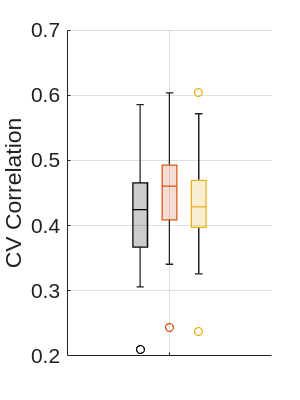

l.Box = "off";
axis('auto')
ylabel('CV Correlation'); grid on; set(gca, 'XtickLabelRotation', 45);
title(''); set(gca, 'FontSize', 16); set(gcf, 'position', [0, 0, 300, 400]); box off; set(gca, 'XtickLabel', '');

% Convert to Fisher z and compare correlations
plot_results = atan(plot_results);
[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,2)) % base vs. expanded adult

h = 1

p = 2.8659e-05

ci =    -0.0343
   -0.0147


stats = struct with fields:
    tstat: -5.1469
       df: 24
       sd: 0.0238


[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,3)) % base vs. expanded pediatric

h = 1

p = 0.0037

ci =    -0.0197
   -0.0043


stats = struct with fields:
    tstat: -3.2114
       df: 24
       sd: 0.0187


[h, p, ci, stats] = ttest(plot_results(:,3), plot_results(:,2)) % expanded adult vs. expanded pediatric

h = 1

p = 0.0082

ci =    -0.0214
   -0.0035


stats = struct with fields:
    tstat: -2.8809
       df: 24
       sd: 0.0216




% Plot results (Spearman)
clf; clear plot_results

% Get CV test fold rank correlations
cv_rho = zeros(5,5);
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    for i = 1:5
        for k = 1:5
            cv_rho(i,k) = corr(results.(modalities{j}).pred_y(:,i,k), results.(modalities{j}).obs_y(:,i,k), 'rows', 'pairwise', 'type', 'Spearman');
        end
    end
    plot_results(:,j) = cv_rho(:);
    clear cv_rho
end

% Plot results
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
if strcmp(beh_col, 'contra_motor')
    b(2).BoxFaceColor = b(1).BoxFaceColor;
    b(2).MarkerColor = b(1).MarkerColor;
else
    b(2).BoxFaceColor = [0.85, 0.325, 0.098];
    b(2).MarkerColor = [0.85, 0.325, 0.098];
end
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l.IconColumnWidth = 10

l = struct with fields:
    IconColumnWidth: 10
                Box: "off"


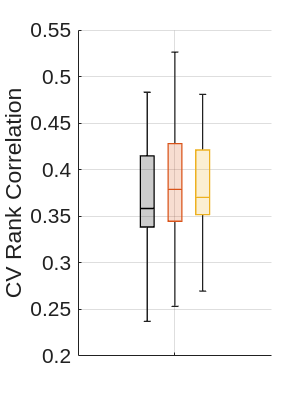

l.Box = "off";
axis('auto')
ylabel('CV Rank Correlation'); grid on; set(gca, 'XtickLabelRotation', 45);
title(''); set(gca, 'FontSize', 16); set(gcf, 'position', [0, 0, 300, 400]); box off; set(gca, 'XtickLabel', '');

plot_results = atan(plot_results);
[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,2)) % base vs. expanded adult

h = 1

p = 0.0198

ci =    -0.0260
   -0.0025


stats = struct with fields:
    tstat: -2.4975
       df: 24
       sd: 0.0285


[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,3)) % base vs. expanded pediatric

h = 1

p = 0.0018

ci =    -0.0168
   -0.0044


stats = struct with fields:
    tstat: -3.5161
       df: 24
       sd: 0.0150


[h, p, ci, stats] = ttest(plot_results(:,3), plot_results(:,2)) % expanded adult vs. expanded pediatric

h = 0

p = 0.3769

ci =    -0.0121
    0.0047


stats = struct with fields:
    tstat: -0.9002
       df: 24
       sd: 0.0204
